## Experimenta data

clc; clear; close all; format shortEng; warning('off','all')

x  = readmatrix('datos.xlsx','Sheet','peso seco');
chl  = readmatrix('datos.xlsx','Sheet','clorofilas');
car = readmatrix('datos.xlsx','Sheet','carotenoides');
n  = readmatrix('datos.xlsx','Sheet','nitratos');
p  = readmatrix('datos.xlsx','Sheet','fosfatos');
u  = readmatrix('datos.xlsx','Sheet','urea');


to = x(1:10,1); 
to = to(:);

nrep = size(x,2)-1; 

## Nonlinear regression


$$$$\dot{x} = x\left(\frac{\mu_{\max} S_N S_P}{S_{N0} S_{P0}} + \frac{\mu_{\max} S_{NU} S_P}{S_{P0} S_{NU0}}\right) - \mu_d x$$



$$$$\dot{Chl} = \mu_{\max}\theta_{Chl} x \left(1 - \frac{Chl}{\phi_{Chl\max}}\right) - \frac{\theta_{Chl} r_P x}{S_P + \varepsilon_{SP}}$$
$$



$$$$\dot{Car} = \mu_{\max}\theta_{Car} x \left(1 - \frac{Car}{\phi_{Car\max}}\right) - \frac{\theta_{Car} r_P x}{S_P + \varepsilon_{SP}}$$
$$



$$$$\dot{S}_N = -\frac{\mu_{\max}\theta_N x S_N}{S_{N0}}$$
$$



$$$$\dot{S}_P = -\frac{\mu_{\max}\theta_P x S_P}{S_{P0}}$$
$$



$$$$\dot{S}_{NU} = -\frac{\mu_{\max}\theta_{NU} x S_{NU}}{S_{NU0}}$$
$$



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>
    ParamNames      Var2         SE         MoE                CI95               pValue  
    __________    ________    ________    ________    ______________________    __________

    {'rho1' }      0.15649    0.033991    0.068307     0.088183       0.2248  

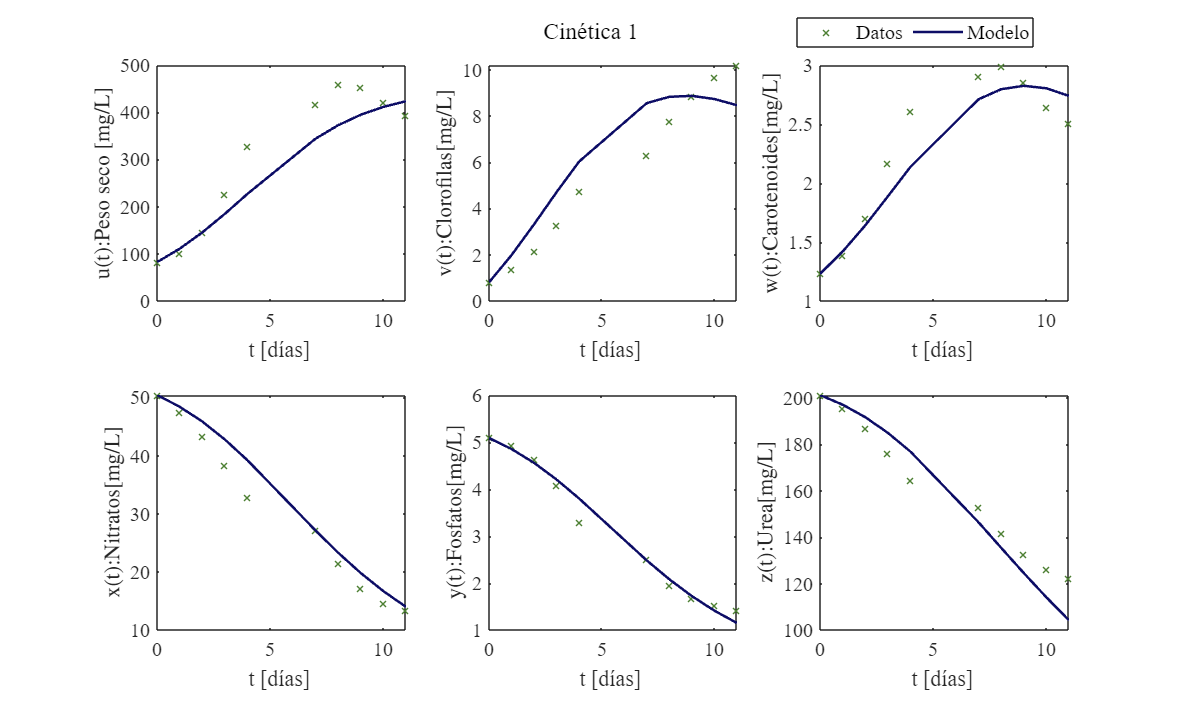


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>
    ParamNames      Var2         SE         MoE                 CI95                pValue  
    __________    ________    ________    ________    ________________________    __________

    {'rho1' }      0.13341     0.01472    0.029581       0.10383       0.1

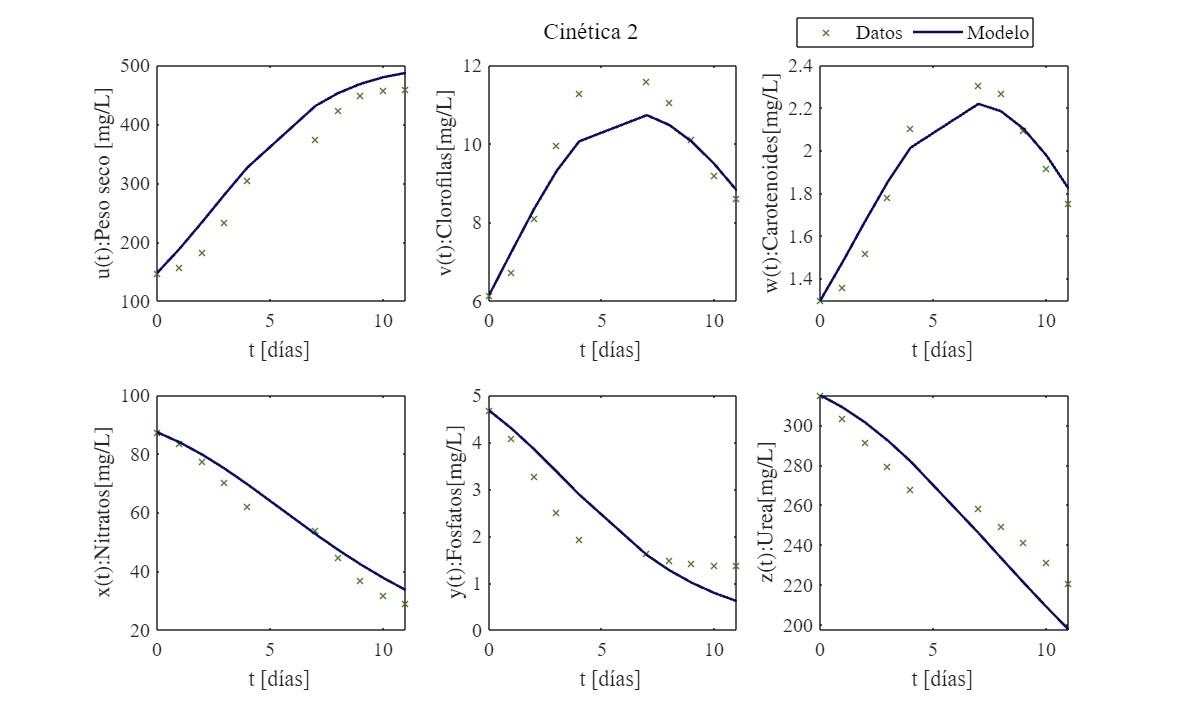


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>
    ParamNames     Var2         SE         MoE                CI95               pValue  
    __________    _______    ________    ________    ______________________    __________

    {'rho1' }     0.13341    0.021499    0.043205     0.090205      0.17661    1

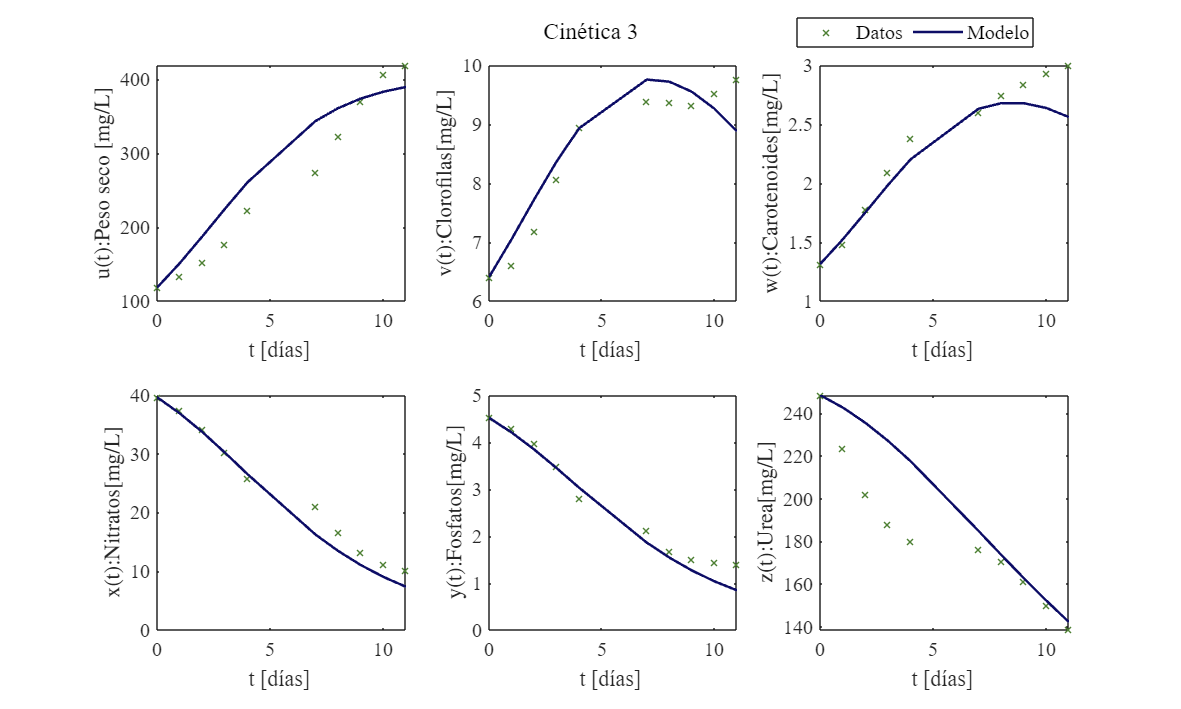

for j = 1:nrep

   
    uo = x(1:10,j+1);
    vo = chl(:,j);  
    wo = car(1:10,j+1);
    xo = n(1:10,j+1);
    yo = p(1:10,j+1);
    zo = u(1:10,j+1);

    %% Suavizado
    us = smoothdata(uo,"gaussian",7);
    vs = smoothdata(vo,"gaussian",7);
    ws = smoothdata(wo,"gaussian",7);
    xs = smoothdata(xo,"gaussian",7);
    ys = smoothdata(yo,"gaussian",7);
    zs = smoothdata(zo,"gaussian",7);

   
    [Estimate, SE, MoE, CI95, pValue, fa, mdl, ua,va,wa,xa,ya,za] = fitting_model(to,us,vs,ws,xs,ys,zs);

 
    plot_Results(to,us,vs,ws,xs,ys,zs,to,ua,va,wa,xa,ya,za,['Cinética ',num2str(j)]);

end

## Functions

### Function: Nonlinear regression algorithm

function [Estimate, SE, MoE, CI95, pValue, fa, mdl, ua,va,wa,xa,ya,za] = ...
         fitting_model(to,usuave,vsuave,wsuave,xsuave,ysuave,zsuave)

    
    to = to(:);
    usuave = usuave(:);
    vsuave = vsuave(:);
    wsuave = wsuave(:);
    xsuave = xsuave(:);
    ysuave = ysuave(:);
    zsuave = zsuave(:);

   
    u0 = usuave(1); v0 = vsuave(1); w0 = wsuave(1);
    x0 = xsuave(1); y0 = ysuave(1); z0 = zsuave(1);

    %% PARÁMETROS 
    rho1 = 0.14724;
    rho2 = x0;
    rho3 = y0;
    rho4 = z0;
    rho5 = 0.005;
    rho6 = 0.11;
    rho7 = 12.5;
    rho8 = 0.075802;
    rho9 = 0.021517;
    rho10 = 3.4;
    rho11 = 0.077;
    rho12 = 0.147637044;
    rho13 = 0.017861744;
    rho14 = 0.261044144;
    rho15 = rho8/rho1;

    P = [rho1,rho5,rho6,rho7,rho8,rho9,rho10,rho11,rho12,rho13,rho14];

   
    fo = [usuave;vsuave;wsuave;xsuave;ysuave;zsuave];
    to_fit = [to;to;to;to;to;to];

    %% Límites 
    low = [0.13341; 0.0045; 0.10 ; 11.25; 0.068; 0.019; 3.1; 0.070; 0.1368; 0.016; 0.28];
    sup = [0.15649; 0.0055; 0.121; 13.75; 0.082; 0.023; 3.7; 0.084; 0.1586; 0.018; 0.33];


    opts = optimoptions('lsqcurvefit',...
        'MaxFunctionEvaluations',300000,...
        'MaxIterations',1E4,...
        'FunctionTolerance',1E-8);

    [Estimate,~,residual,~,~,~,J] = lsqcurvefit(@modelo,P,to_fit,fo,low,sup,opts);

    fa = modelo(Estimate,to_fit);

    
    dof = numel(fo) - length(P);
    covv = inv(J'*J)*(residual'*residual/dof);
    SE = sqrt(diag(covv));

    tval = tinv(0.975,dof);
    MoE = SE * tval;

    CI95 = [Estimate'-MoE, Estimate'+MoE];

    t_stat = Estimate'./SE;
    pValue = 2*(1 - tcdf(abs(t_stat),dof));

    mdl = table(Estimate',SE,MoE,pValue);

  
    fa_r = reshape(fa,[],6);
    ua=fa_r(:,1); va=fa_r(:,2); wa=fa_r(:,3);
    xa=fa_r(:,4); ya=fa_r(:,5); za=fa_r(:,6);

    
    ParamNames = {'rho1';'rho5';'rho6';'rho7';'rho8';'rho9';'rho10';'rho11';'rho12';'rho13';'rho14'};
    Results = table(ParamNames,Estimate',SE,MoE,CI95,pValue);
    disp(Results)

    function fa = modelo(P,t)

        t = reshape(t,[],6); t = t(:,1);

        rho1=P(1); rho5=P(2); rho6=P(3); rho7=P(4);
        rho8=P(5); rho9=P(6); rho10=P(7); rho11=P(8);
        rho12=P(9); rho13=P(10); rho14=P(11);

        dt = 1E-2;
        time = (0:dt:max(t))';
        n = length(time)-1;

        u=zeros(n+1,1); v=u; w=u; x=u; y=u; z=u;
        u(1)=u0; v(1)=v0; w(1)=w0; x(1)=x0; y(1)=y0; z(1)=z0;

        for i=1:n
            [du,dv,dw,dx,dy,dz]=f(u(i),v(i),w(i),x(i),y(i),z(i));

            un=u(i)+du*dt;
            vn=v(i)+dv*dt;
            wn=w(i)+dw*dt;
            xn=x(i)+dx*dt;
            yn=y(i)+dy*dt;
            zn=z(i)+dz*dt;

            [dun,dvn,dwn,dxn,dyn,dzn]=f(un,vn,wn,xn,yn,zn);

            u(i+1)=u(i)+(du+dun)*dt/2;
            v(i+1)=v(i)+(dv+dvn)*dt/2;
            w(i+1)=w(i)+(dw+dwn)*dt/2;
            x(i+1)=x(i)+(dx+dxn)*dt/2;
            y(i+1)=y(i)+(dy+dyn)*dt/2;
            z(i+1)=z(i)+(dz+dzn)*dt/2;
        end

        
        uk=zeros(length(t),1);
        vk=zeros(length(t),1);
        wk=zeros(length(t),1);
        xk=zeros(length(t),1);
        yk=zeros(length(t),1);
        zk=zeros(length(t),1);

        for i=1:length(t)
            k=abs(time-t(i))<1E-9;
            uk(i)=u(k);
            vk(i)=v(k);
            wk(i)=w(k);
            xk(i)=x(k);
            yk(i)=y(k);
            zk(i)=z(k);
        end

        fa=[uk;vk;wk;xk;yk;zk];

        function [du,dv,dw,dx,dy,dz]=f(u,v,w,x,y,z)
            du = (u*((rho1*x/rho2)*(y/rho3)+(rho1*z/rho4)*(y/rho3)))-(rho5*u);
            dv = (rho1*rho6*u*(1-(v/rho7)))-(rho6*rho8*u/(y+rho15));
            dw = (rho1*rho9*u*(1-(w/rho10)))-(rho9*rho11*u/(y+rho15));
            dx = (-rho1*rho12*u*x)/rho2;
            dy = (-rho1*rho13*u*y)/rho3;
            dz = (-rho1*rho14*u*z)/rho4;
        end
    end
end

### Plot:

function plot_Results(to, ue, ve, we, xe, ye, ze, time, ua, va, wa, xa, ya, za, titulo)

    set(figure(),'Color','w');
    set(gcf,'Units','Centimeters','Position',[2 2 25 15]);
    FS = 12;

    v_exp = {ue,ve,we,xe,ye,ze};
    v_mod = {ua,va,wa,xa,ya,za};

    labels = {'u(t):Peso seco [mg/L]','v(t):Clorofilas [mg/L]','w(t):Carotenoides [mg/L]','x(t):Nitratos [mg/L]','y(t):Fosfatos [mg/L]','z(t):Urea [mg/L]'};

    for i = 1:6
        subplot(2,3,i); hold on; box on;

        
        plot(to, v_exp{i}, 'x', 'LineWidth',1,'MarkerSize',5,'Color',[0.3 0.5 0.2]);

 
        plot(time, v_mod{i}, '-', 'LineWidth',1.5,'Color',[0.05 0.05 0.4]);

        xlabel('t [días] ','Interpreter','latex','FontSize',FS);
        ylabel(labels{i},'Interpreter','latex','FontSize',FS);

        set(gca,'FontName','Times New Roman','FontSize',FS);
         
    end
    lgd = legend({'Datos', 'Modelo'}, 'FontName', 'Times New Roman', 'FontSize', FS);
    lgd.Orientation = 'horizontal';
    lgd.Position = [0.70, 0.94, 0.15, 0.03]; 

    sgtitle(titulo,'Interpreter', 'latex', 'FontSize', FS + 2, 'FontName', 'Times New Roman');
end